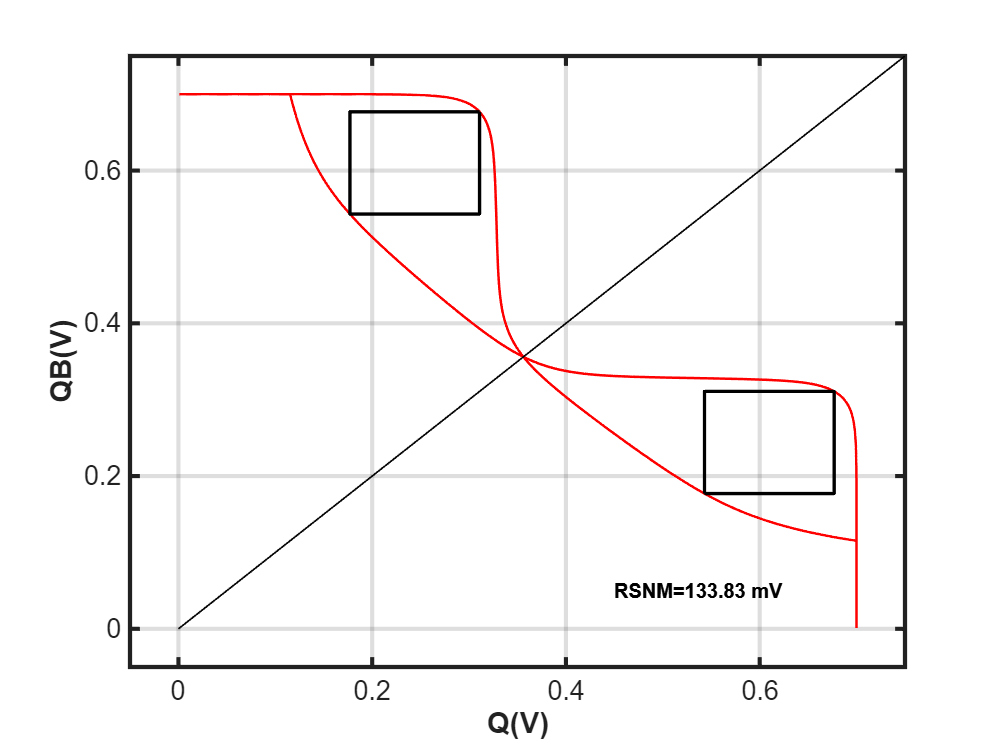

clear; clc; close all;

%% 1. 加载所有数据
data1 = load("D:\GitHub\Matlab\Data\read_snm\read122_QvsQB.mat");
read122_QvsQB = data1.read122_QvsQB; clear data1;
data2 = load("D:\GitHub\Matlab\Data\read_snm\read122_QBvsQ.mat");
read122_QBvsQ = data2.read122_QBvsQ; clear data2;

data1 = load("D:\GitHub\Matlab\Data\read_snm\read111_QvsQB.mat");
read111_QvsQB = data1.read111_QvsQB; clear data1;
data2 = load("D:\GitHub\Matlab\Data\read_snm\read111_QBvsQ.mat");
read111_QBvsQ = data2.read111_QBvsQ; clear data2;

data1 = load("D:\GitHub\Matlab\Data\read_snm\read112_QvsQB.mat");
read112_QvsQB = data1.read112_QvsQB; clear data1;
data2 = load("D:\GitHub\Matlab\Data\read_snm\read112_QBvsQ.mat");
read112_QBvsQ = data2.read112_QBvsQ; clear data2;

%% 2. 提取数据
X1 = read122_QvsQB.Q; Y1 = read122_QvsQB.QB;
X2 = read122_QBvsQ.Q; Y2 = read122_QBvsQ.QB;
X3 = read111_QvsQB.Q; Y3 = read111_QvsQB.QB;
X4 = read111_QBvsQ.Q; Y4 = read111_QBvsQ.QB;
X5 = read112_QvsQB.Q; Y5 = read112_QvsQB.QB;
X6 = read112_QBvsQ.Q; Y6 = read112_QBvsQ.QB;

%% 3. 输出路径与通用参数（统一修改所有图样式）
outputPath = 'D:\同步\毕业设计\毕业设计\毕业论文\Figure';
if ~exist(outputPath, 'dir'), mkdir(outputPath); end

figPos = [100, 100, 800, 600];    % 窗口大小
axisRange = [-0.05, 0.75];        % 坐标轴范围
tickStep = 0:0.2:0.8;             % 网格间距0.2
curveWidth = 1.5;                 % 曲线线宽
axisWidth = 2.5;                  % 坐标轴线宽
fontSize = 16;                    % 刻度字体大小
labelSize = 14;                   % 标签字体大小
squareWidth = 2;                  % 正方形线宽
squareColor = 'k';                % 正方形颜色（黑色）
textOffset = 0.02;                % 标注文字偏移量

%% 4. 生成122工况蝴蝶曲线（红色）并计算RSNM
figure('Position', figPos);
hold on;
plot(X1, Y1, 'r-', 'LineWidth', curveWidth);
plot(X2, Y2, 'r-', 'LineWidth', curveWidth);
plot([0, 0.8], [0, 0.8], 'k-', 'LineWidth', 1); % 黑色对角线（更清晰）
grid on; box on;

% 计算RSNM并绘制正方形
[rsnm122, square1_122, square2_122] = calculate_rsnm(X1, Y1, X2, Y2, axisRange);

% 绘制两个正方形
plot(square1_122(1,:), square1_122(2,:), [squareColor '-'], 'LineWidth', squareWidth);
plot(square2_122(1,:), square2_122(2,:), [squareColor '-'], 'LineWidth', squareWidth);

% 标注RSNM值
text(0.45, 0.05, ...
    sprintf('RSNM=%.2f mV', rsnm122(1)*1000), ...
    'FontSize', labelSize-2, 'FontWeight', 'bold', 'Color', squareColor);
text(0.45, 0.05,...
    sprintf('RSNM=%.2f mV', rsnm122(2)*1000), ...
    'FontSize', labelSize-2, 'FontWeight', 'bold', 'Color', squareColor);

xlabel('Q(V)', 'FontSize', labelSize, 'FontWeight', 'bold');
ylabel('QB(V)', 'FontSize', labelSize, 'FontWeight', 'bold');
xlim(axisRange); ylim(axisRange);
xticks(tickStep); yticks(tickStep);
set(gca, 'FontSize', fontSize, 'LineWidth', axisWidth);
legend off; hold off;

matlab2tikz(fullfile(outputPath, 'butterfly_122.tex'), ...
    'showInfo', false, ...
    'parseStrings', false);

disp('✓ butterfly_122.tex 已生成');

✓ butterfly_122.tex 已生成


disp(['  122工况RSNM(存储0): ', num2str(rsnm122(1)*1000), ' mV']);

  122工况RSNM(存储0): 133.8278 mV


disp(['  122工况RSNM(存储1): ', num2str(rsnm122(2)*1000), ' mV']);

  122工况RSNM(存储1): 133.8278 mV


disp(['  122工况最小RSNM: ', num2str(min(rsnm122)*1000), ' mV']);

  122工况最小RSNM: 133.8278 mV


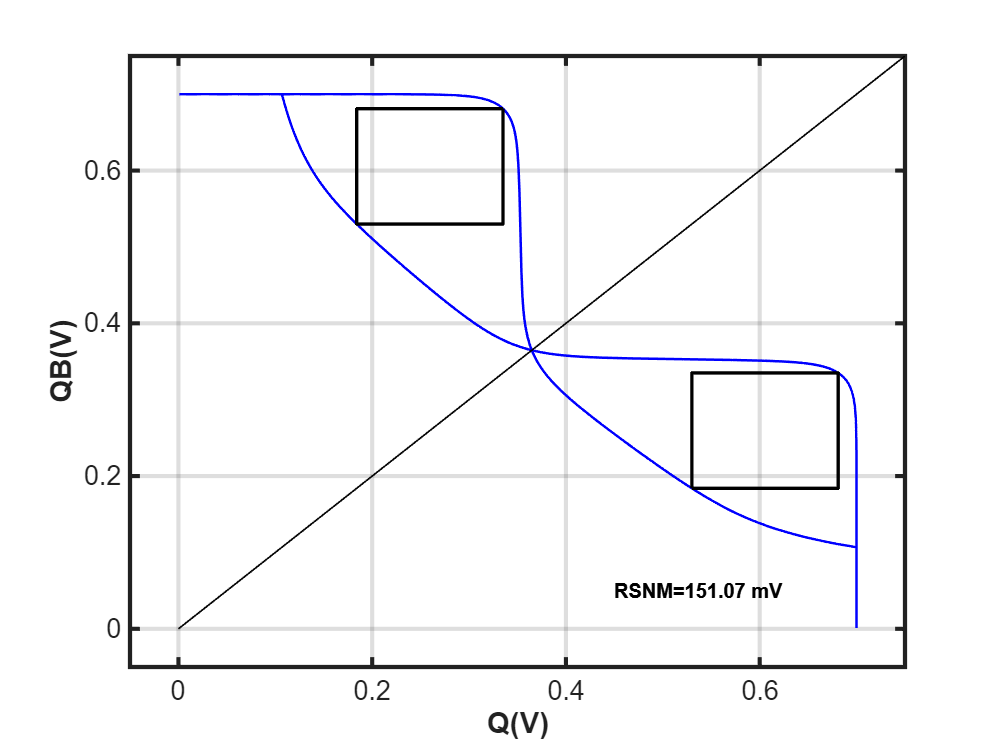


%% 5. 生成111工况蝴蝶曲线（蓝色）并计算RSNM
figure('Position', figPos);
hold on;
plot(X3, Y3, 'b-', 'LineWidth', curveWidth);
plot(X4, Y4, 'b-', 'LineWidth', curveWidth);
plot([0, 0.8], [0, 0.8], 'k-', 'LineWidth', 1);
grid on; box on;

% 计算RSNM并绘制正方形
[rsnm111, square1_111, square2_111] = calculate_rsnm(X3, Y3, X4, Y4, axisRange);

% 绘制两个正方形
plot(square1_111(1,:), square1_111(2,:), [squareColor '-'], 'LineWidth', squareWidth);
plot(square2_111(1,:), square2_111(2,:), [squareColor '-'], 'LineWidth', squareWidth);

% 标注RSNM值
text(0.45, 0.05, ...
    sprintf('RSNM=%.2f mV', rsnm111(1)*1000), ...
    'FontSize', labelSize-2, 'FontWeight', 'bold', 'Color', squareColor);
text(0.45, 0.05,...
    sprintf('RSNM=%.2f mV', rsnm111(2)*1000), ...
    'FontSize', labelSize-2, 'FontWeight', 'bold', 'Color', squareColor);

xlabel('Q(V)', 'FontSize', labelSize, 'FontWeight', 'bold');
ylabel('QB(V)', 'FontSize', labelSize, 'FontWeight', 'bold');
xlim(axisRange); ylim(axisRange);
xticks(tickStep); yticks(tickStep);
set(gca, 'FontSize', fontSize, 'LineWidth', axisWidth);
legend off; hold off;

matlab2tikz(fullfile(outputPath, 'butterfly_111.tex'), ...
    'showInfo', false, ...
    'parseStrings', false);

disp('✓ butterfly_111.tex 已生成');

✓ butterfly_111.tex 已生成


disp(['  111工况RSNM(存储0): ', num2str(rsnm111(1)*1000), ' mV']);

  111工况RSNM(存储0): 151.0654 mV


disp(['  111工况RSNM(存储1): ', num2str(rsnm111(2)*1000), ' mV']);

  111工况RSNM(存储1): 151.0654 mV


disp(['  111工况最小RSNM: ', num2str(min(rsnm111)*1000), ' mV']);

  111工况最小RSNM: 151.0654 mV


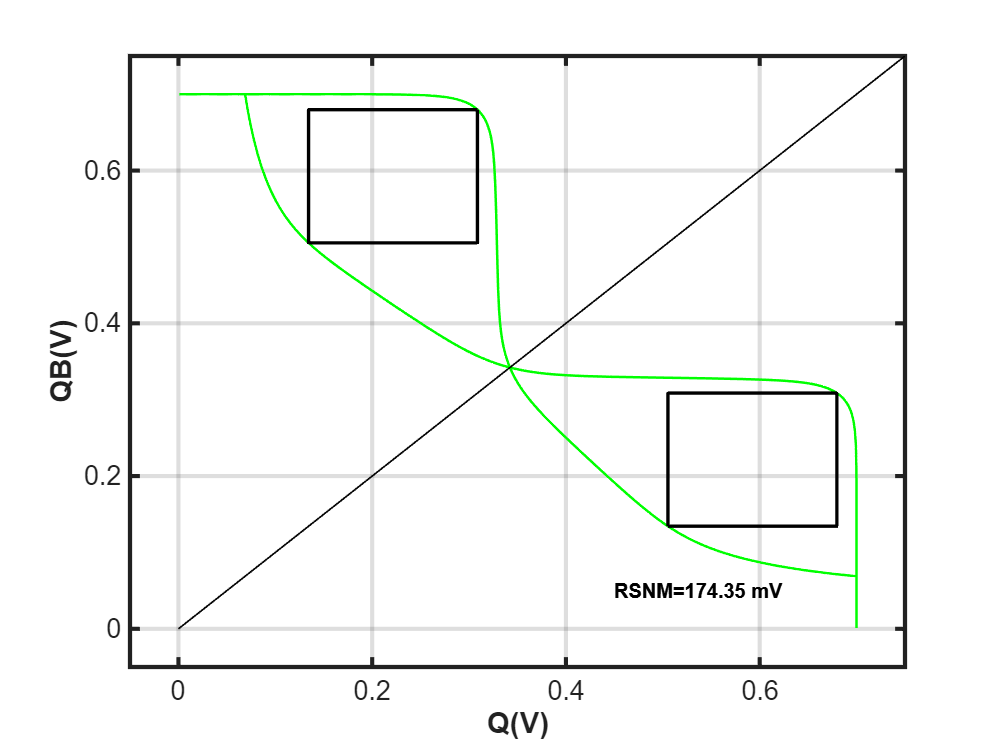


%% 6. 生成112工况蝴蝶曲线（绿色）并计算RSNM
figure('Position', figPos);
hold on;
plot(X5, Y5, 'g-', 'LineWidth', curveWidth);
plot(X6, Y6, 'g-', 'LineWidth', curveWidth);
plot([0, 0.8], [0, 0.8], 'k-', 'LineWidth', 1);
grid on; box on;

% 计算RSNM并绘制正方形
[rsnm112, square1_112, square2_112] = calculate_rsnm(X5, Y5, X6, Y6, axisRange);

% 绘制两个正方形
plot(square1_112(1,:), square1_112(2,:), [squareColor '-'], 'LineWidth', squareWidth);
plot(square2_112(1,:), square2_112(2,:), [squareColor '-'], 'LineWidth', squareWidth);

% 标注RSNM值
text(0.45, 0.05, ...
    sprintf('RSNM=%.2f mV', rsnm112(1)*1000), ...
    'FontSize', labelSize-2, 'FontWeight', 'bold', 'Color', squareColor);
text(0.45, 0.05, ...
    sprintf('RSNM=%.2f mV', rsnm112(2)*1000), ...
    'FontSize', labelSize-2, 'FontWeight', 'bold', 'Color', squareColor);

xlabel('Q(V)', 'FontSize', labelSize, 'FontWeight', 'bold');
ylabel('QB(V)', 'FontSize', labelSize, 'FontWeight', 'bold');
xlim(axisRange); ylim(axisRange);
xticks(tickStep); yticks(tickStep);
set(gca, 'FontSize', fontSize, 'LineWidth', axisWidth);
legend off; hold off;

matlab2tikz(fullfile(outputPath, 'butterfly_112.tex'), ...
    'showInfo', false, ...
    'parseStrings', false);

disp('✓ butterfly_112.tex 已生成');

✓ butterfly_112.tex 已生成


disp(['  112工况RSNM(存储0): ', num2str(rsnm112(1)*1000), ' mV']);

  112工况RSNM(存储0): 174.3532 mV


disp(['  112工况RSNM(存储1): ', num2str(rsnm112(2)*1000), ' mV']);

  112工况RSNM(存储1): 174.3532 mV


disp(['  112工况最小RSNM: ', num2str(min(rsnm112)*1000), ' mV']);

  112工况最小RSNM: 174.3532 mV



%% 完成提示
disp(' ');

disp(['✅ 所有3张蝴蝶曲线已保存至：' outputPath]);

✅ 所有3张蝴蝶曲线已保存至：D:\同步\毕业设计\毕业设计\毕业论文\Figure


disp(' ');

disp('📊 工况对比总结:');

📊 工况对比总结:


disp(['  122工况最小RSNM: ', num2str(min(rsnm122)*1000), ' mV']);

  122工况最小RSNM: 133.8278 mV


disp(['  111工况最小RSNM: ', num2str(min(rsnm111)*1000), ' mV']);

  111工况最小RSNM: 151.0654 mV


disp(['  112工况最小RSNM: ', num2str(min(rsnm112)*1000), ' mV']);

  112工况最小RSNM: 174.3532 mV



%% ==================== 核心函数定义 ====================
% 计算RSNM和最大内接正方形
function [rsnm, square1, square2] = calculate_rsnm(X1, Y1, X2, Y2, axisRange)
    % 输入:
    %   X1,Y1: 第一条曲线(QvsQB)的坐标
    %   X2,Y2: 第二条曲线(QBvsQ)的坐标
    %   axisRange: 坐标轴范围 [xmin, xmax]
    % 输出:
    %   rsnm: 两个正方形的RSNM值 [rsnm0, rsnm1] (存储0和存储1)
    %   square1, square2: 两个正方形的顶点坐标 (2x5矩阵，最后一个点与第一个点闭合)
    
    % 准备曲线数据 (InterX函数要求2xN矩阵)
    curve1 = [X1(:)'; Y1(:)'];
    curve2 = [X2(:)'; Y2(:)'];
    
    % 生成平行于y=x的直线扫描范围
    k_min = axisRange(1) - axisRange(2); % 最小偏移量 (y=x+k, k为负时在对角线下方)
    k_max = axisRange(2) - axisRange(1); % 最大偏移量 (k为正时在对角线上方)
    k_step = 1e-3; % 扫描步长，越小精度越高但计算越慢
    k_values = k_min:k_step:k_max;
    
    max_dist1 = 0; % 存储0状态的最大对角线长度
    max_dist2 = 0; % 存储1状态的最大对角线长度
    best_k1 = 0;   % 存储0状态的最佳k值
    best_k2 = 0;   % 存储1状态的最佳k值
    
    % 扫描所有平行于y=x的直线
    for k = k_values
        % 生成当前直线 y = x + k
        line_x = linspace(axisRange(1), axisRange(2), 2);
        line_y = line_x + k;
        line = [line_x; line_y];
        
        % 计算直线与两条曲线的交点
        P1 = InterX(curve1, line);
        P2 = InterX(curve2, line);
        
        % 如果直线与两条曲线都有且只有一个交点
        if size(P1, 2) == 1 && size(P2, 2) == 1
            % 计算两个交点之间的距离
            dist = sqrt((P1(1)-P2(1))^2 + (P1(2)-P2(2))^2);
            
            % 判断属于哪个正方形 (根据交点在对角线的哪一侧)
            if k < 0 % 对角线下方，对应存储0状态
                if dist > max_dist1
                    max_dist1 = dist;
                    best_k1 = k;
                end
            else % 对角线上方，对应存储1状态
                if dist > max_dist2
                    max_dist2 = dist;
                    best_k2 = k;
                end
            end
        end
    end
    
    % 计算RSNM (边长 = 对角线长度 / sqrt(2))
    rsnm = [max_dist1/sqrt(2), max_dist2/sqrt(2)];
    
    % 计算最佳直线与曲线的交点
    line1_x = linspace(axisRange(1), axisRange(2), 2);
    line1_y = line1_x + best_k1;
    line1 = [line1_x; line1_y];
    P1_1 = InterX(curve1, line1);
    P1_2 = InterX(curve2, line1);
    
    line2_x = linspace(axisRange(1), axisRange(2), 2);
    line2_y = line2_x + best_k2;
    line2 = [line2_x; line2_y];
    P2_1 = InterX(curve1, line2);
    P2_2 = InterX(curve2, line2);
    
    % 根据对角线端点计算正方形的另外两个顶点
    square1 = calculate_square_vertices(P1_1, P1_2);
    square2 = calculate_square_vertices(P2_1, P2_2);
end

% 根据对角线两个端点计算正方形的四个顶点 (边与坐标轴成45度角)
function square = calculate_square_vertices(P1, P2)
    % 输入:
    %   P1, P2: 对角线的两个端点 (2x1向量)
    % 输出:
    %   square: 正方形的四个顶点坐标 (2x5矩阵，最后一个点与第一个点闭合)
    
    % 计算中点
    M = (P1 + P2) / 2;
    
    % 计算从P1到P2的向量
    v = P2 - P1;
    
    % 将向量旋转90度得到垂直向量 (逆时针旋转)
    v_rot = [-v(2); v(1)];
    
    % 正方形的另外两个顶点
    P3 = M + v_rot/2;
    P4 = M - v_rot/2;
    
    % 组成正方形顶点矩阵 (按顺序连接，最后回到起点)
    square = [P1, P3, P2, P4, P1];
end

% 曲线交点计算函数 (来自MATLAB File Exchange, 作者: Douglas M. Schwarz)
function P = InterX(L1,varargin)
    %INTERX Intersection of curves
    %   P = INTERX(L1,L2) returns the intersection points of two curves L1 
    %   and L2. The curves L1,L2 can be either closed or open and are described
    %   by two-row-matrices, where each row contains its x- and y- coordinates.
    %   The intersection of groups of curves (e.g. contour lines, multiply
    %   connected regions etc) can also be computed by separating them with a
    %   column of NaNs.
    %
    %   P = INTERX(L1) returns the self-intersection points of L1. To keep
    %   the code simple, the points at which the curve is tangent to itself are
    %   not included. P = INTERX(L1,L1) returns all the points of the curve
    %   together with any self-intersection points.
    %
    %   Example:
    %       t = linspace(0,2*pi);
    %       r1 = sin(4*t)+2;  x1 = r1.*cos(t); y1 = r1.*sin(t);
    %       r2 = sin(8*t)+2;  x2 = r2.*cos(t); y2 = r2.*sin(t);
    %       P = InterX([x1;y1],[x2;y2]);
    %       plot(x1,y1,x2,y2,P(1,:),P(2,:),'ro')
    
    %   Author : NS
    %   Version: 3.0, 21 Sept. 2010
    
    narginchk(1,2);
    
    % F. de Castro, 2017: Handle empty inputs
    if isempty(L1)
        P = [];
        return;
    end
    
    % L2 is given?
    L2 = varargin{1};
    if nargin==1
        self = true;
        L2 = L1;
    else
        self = false;
        % F. de Castro, 2017: Handle empty inputs
        if isempty(L2)
            P = [];
            return;
        end
    end
    
    % Remove NaNs and collect curve segments
    h1 = ~isnan(L1(1,:));
    L1 = L1(:,h1);
    d1 = diff(L1,1,2);
    n1 = size(d1,2);
    
    h2 = ~isnan(L2(1,:));
    L2 = L2(:,h2);
    d2 = diff(L2,1,2);
    n2 = size(d2,2);
    
    % Preallocate
    P = zeros(2,0);
    
    % Loop through all segments of L1
    for i = 1:n1
        % Current segment of L1
        a1 = L1(:,i);
        a2 = L1(:,i+1);
        da = a2 - a1;
        
        % Loop through all segments of L2
        for j = 1:n2
            % Skip self-intersection at common vertices
            if self && (i==j || (self && i==j+1))
                continue;
            end
            
            % Current segment of L2
            b1 = L2(:,j);
            b2 = L2(:,j+1);
            db = b2 - b1;
            
            % Solve for t and s: a1 + t*da = b1 + s*db
            % Rewrite as: [da -db] * [t;s] = b1 - a1
            A = [da, -db];
            B = b1 - a1;
            
            % Check if lines are parallel
            if abs(det(A)) < eps
                continue;
            end
            
            % Solve the system
            ts = A\B;
            t = ts(1);
            s = ts(2);
            
            % Check if intersection is within the segments
            if t >= -eps && t <= 1+eps && s >= -eps && s <= 1+eps
                % Clamp to [0,1] to avoid numerical issues
                t = max(0, min(1, t));
                s = max(0, min(1, s));
                
                % Compute intersection point
                p = a1 + t*da;
                
                % Add to list (avoid duplicates)
                if isempty(P) || ~any(all(abs(P - p) < 1e-10, 1))
                    P = [P, p];
                end
            end
        end
    end
end